clc;
clear;
close all

%方程参数
a = 0.888;
w = 1.888;
phi = 0.25*pi;
L = -1;%L = 1 逆时针 L=-1顺时针
iteration = 100; %迭代次数
pret = 0.3; %预测时间
dt = 0.010;
%其他参数 以R标为坐标原点
radius = 700; %mm

fn_angle = @(t) L*(-a*cos(w*t + phi)./w +(2.090-a)*t);

fn_omega = @(t) L*(a*sin(w*t+phi) + 2.090 - a);
t0 = 1.01:dt:15;
angle = fn_angle(t0);
% rand72 = 0;
tiaobiantime = 2.5;
% 2.5s后随机跳变72度的整数倍
for i = 1:1:floor(t0(end)/tiaobiantime)
    ttt = (t0 - t0(1))./tiaobiantime;
    flag = i+1>ttt & ttt>i;
    rand72 = randi([1, 4])*2*pi/5;
    angle(flag) = angle(flag)+rand72;
end

theta = mod(angle, 2*pi);
theta_0 = theta(1);
% plot(t0, theta, "*")

%kalman
H = [1, 0, 0, 0;
     0, 1, 0, 0];
Q = [0.01 0.001 0     0;
     0.001 0.01 0     0;
     0      0  0.01 0.001;
     0      0  0.001 0.01];
R = [0.0001 0;
    0 0.0001];
P = zeros(4);

K = zeros(4, 2);
% a, w输入与真实差一点点来模拟pso迭代出的参数
X = [radius*cos(theta_0); radius*sin(theta_0); fn_omega(1.01); phi];

%real
pre_index = floor(pret/dt)+2+iteration:1:length(t0);
real_x = radius*cos(theta(pre_index));
real_y = radius*sin(theta(pre_index));
% for i =1:length(real_x)
%     plot(real_x(i),real_y(i),"*")
%     hold on 
%     pause(0.1)
% end
% hold off
%predict 
pre_x = [];
pre_y = [];
r_noise = (0.1/360) * 2 * pi*randn(1,length(theta));
z_ = theta + r_noise; % 观测加噪声0.1度高斯噪声
% plot(1:length(theta),z_-theta)

aim_x = [];
aim_y = [];
a = a*0.9;
w = w*0.9;
for i = 2:length(theta)
    dt = t0(i) - t0(i-1);
    t = t0(i-1);
    x = X(1);
    y = X(2);
    omega = X(3);
    phi = X(4);
%     if (5*2*pi/6) >(z_(i)-z_(i-1))&&(z_(i)-z_(i-1))>2*pi/6
%         disp((z_(i)-z_(i-1))/(2*pi) *360)
%         plot(x,y,"b*")
%         hold on
%         x = x*cos(z_(i)-z_(i-1))-y*sin(z_(i)-z_(i-1));
%         y = y*cos(z_(i)-z_(i-1))+x*sin(z_(i)-z_(i-1));
%         plot(x,y,"r*")
%         hold off
%     end
    A = [x*cos(omega*dt) - y*sin(omega*dt);
        y*cos(omega*dt) + x*sin(omega*dt);
        L*(a*sin(w*(t+dt) + phi) + 2.090 - a);
        phi];


    Jac = [cos(dt*omega), -sin(dt*omega), -dt*y*cos(dt*omega) - dt*x*sin(dt*omega), 0;
        sin(dt*omega), cos(dt*omega),  dt*x*cos(dt*omega) - dt*y*sin(dt*omega), 0;
        0, 0, 0, L*a*cos(phi + w*(dt + t));
        0, 0, 0, 1;];
    
    %预测
    X = A;
    
    pre_x = [pre_x, X(1, 1)];
    pre_y = [pre_y, X(2, 1)];
    P = Jac * P * Jac' + Q;
    
    %更新
    Z = [radius*cos(z_(i));
        radius*sin(z_(i))];

    K = P * H' / (H * P * H' + R);
    X = X + K * (Z - H * X);
    P = (eye(size(P)) - K * H) * P;
    if i ==150
       disp(P) 
       disp(A(3))
    end
    if length(theta)-30>=i && i>=iteration+2
        [m,n] = predicted(X,a,w,t,pret,L);
        aim_x = [aim_x, m];
        aim_y = [aim_y, n];
    end
end

    0.0001   -0.0000    0.0000   -0.0000
   -0.0000    0.0001   -0.0000    0.0000
    0.0000   -0.0000    0.0168   -0.0156
   -0.0000    0.0000   -0.0156    0.0510



   -0.6025



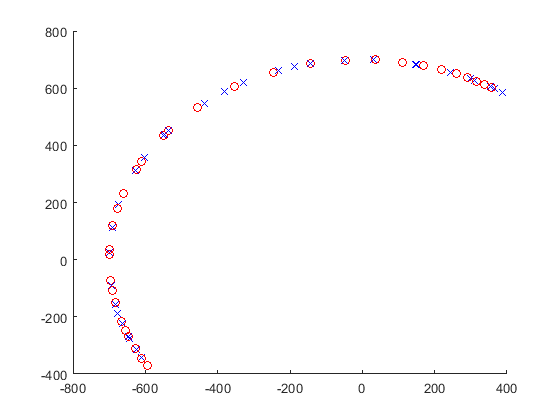




% 初始化图形并保持
figure;
hold on;

for i = 1:10:length(real_y)
    % 绘制实际点
    plot(real_x(1, i), real_y(1, i), 'ro')
    hold on 
%     plot(radius*cos(z_(i+1)),radius*sin(z_(i+1)),"g*")
% %     绘制预测点
%     plot(pre_x(1, i), pre_y(1, i), 'b+')
    plot(aim_x(1, i), aim_y(1, i), 'bx')
%     legend(["真实","观测","预测dt","预测0.5s"])
    % 暂停一段时间
    pause(1)
end

error = ((real_x-aim_x).^2+(real_y-aim_y).^2).^0.5;
error(error>100) = 0;
rmse = sum(error)/length(real_y);
disp([rmse,"mm"])
% 释放图形，以便绘制新的图形
hold off;

plot(real_x, real_y, 'ro-', 'MarkerSize', 3);
hold on;
plot(pre_x, pre_y, 'b+-', 'MarkerSize', 4);
% plot(0, 0, 'g*', 'MarkerSize', 20);
hold on;


% 设置坐标轴的标签和标题
xlabel('X Position (mm)');
ylabel('Y Position (mm)');
title('Actual vs Predicted Points');
legend("real", 'predict');

% 添加网格线
grid on;

% 设置坐标轴比例
axis equal;
